=== Loading Model and Parameters from Q2 ===


Loaded plant model "Plant (ARX from Q1/Q2)" and Ts = 0.050 s from Q2_DynamicsAnalysis.mat


Using plant for PID design with Ts = 0.050 s.



=== (a) Design 1: Minimize Overshoot (<5%) ===


Gains for Min Overshoot PID (<5%): Kp=7.0270, Ki=4.1665, Kd=2.9628



=== (b) Design 2: Minimize Settling Time (<1s) ===


Gains for Min Settling Time PID (<1s): Kp=746.0000, Ki=2212.0000, Kd=63.0000



=== (c) Design 3: Balanced Design ===


Gains for Balanced PID: Kp=52.3800, Ki=31.6300, Kd=21.6800



=== Simulating Closed-Loop Systems and Extracting Metrics ===


Analyzing step response for "Min Overshoot PID (<5%)"...


Analyzing step response for "Min Settling Time PID (<1s)"...


Analyzing step response for "Balanced PID"...




--- DELIVERABLE (Q3a): Controller Gains ---


         PID_Design_Objective           Kp        Ki        Kd  
    _______________________________    _____    ______    ______

    {'Min Overshoot PID (<5%)'    }    7.027    4.1665    2.9628
    {'Min Settling Time PID (<1s)'}      746      2212        63
    {'Balanced PID'               }    52.38     31.63     21.68





--- DELIVERABLE (Q3b part 1): Performance Metrics Summary ---


         PID_Design_Objective          Overshoot_Percent    SettlingTime_2pct_sec    RiseTime_10_90_sec    PeakValue    PeakTime_sec    SteadyStateError_to_Step1
    _______________________________    _________________    _____________________    __________________    _________    ____________    _________________________

    {'Min Overshoot PID (<5%)'    }         0.16419                 4.45                     0.5            1.0016           0.9               0.00065878        
    {'Min Settling Time PID (<1s)'}          20.548                  0.2                    0.05            1.2055          0.05                        0        
    {'Balanced PID'               }          3.4725                 0.45                     0.1            1.034


Note on Target Criteria Met:


  - Design 1 (Min Overshoot < 5%): Achieved = YES (Actual: 0.16%)


  - Design 2 (Min Settling Time < 1s): Achieved = YES (Actual: 0.20s)



--- DELIVERABLE (Q3b part 2): Simulations (Step Response Plots) ---


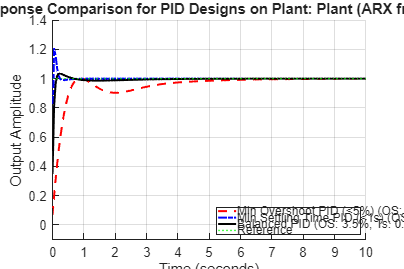



--- DELIVERABLE (Q3c): Trade-off Analysis and Justification of Preferred Design ---


************************************************************************************


INSTRUCTIONS: Based on the tables and plots above, provide your analysis and justification below.


Replace bracketed text like "[Your analysis here...]" with your own findings and reasoning.


************************************************************************************



1. TRADE-OFF ANALYSIS:



   Design 1: PID Controller to Minimize Overshoot (<5%)


   - Controller Gains: Kp=7.027, Ki=4.167, Kd=2.963


   - Achieved Performance: Overshoot = 0.16%, Settling Time = 4.450s, Rise Time = 0.500s


   - Observations: [Discuss how the low overshoot target was met. How did this impact the settling time and rise time compared to other designs? Was the response sluggish? Note any specific tuning challenges or behaviors.]



   Design 2: PID Controller to Minimize Settling Time (<1s)


   - Controller Gains: Kp=746.000, Ki=2212.000, Kd=63.000


   - Achieved Performance: Overshoot = 20.55%, Settling Time = 0.200s, Rise Time = 0.050s


   - Observations: [Discuss how the fast settling time target was met. What was the impact on overshoot? Was the control action aggressive? Note any specific tuning challenges or behaviors.]



   Design 3: Balanced PID Controller


   - Controller Gains: Kp=52.380, Ki=31.630, Kd=21.680


   - Achieved Performance: Overshoot = 3.47%, Settling Time = 0.450s, Rise Time = 0.100s


   - Observations: [Describe the characteristics of this design. How does it compare to the specialized designs in terms of overshoot, settling time, and overall responsiveness? Does it offer a good compromise?]



   Overall Trade-offs:


   [Summarize the key trade-offs observed between overshoot, settling time, rise time, and potentially control effort (inferred from gain magnitudes or aggressiveness of response). For example, aggressive tuning for speed often increases overshoot.]




2. EVALUATION AND JUSTIFICATION OF PREFERRED DESIGN:



   Preferred Design Choice: [State which of the three designs (Minimize Overshoot, Minimize Settling Time, or Balanced) you select as your preferred design for the UAV vertical motion control.]



   Justification:


   [Provide a detailed justification for your choice. Consider the following aspects:


    - Safety and Stability: How does your chosen design ensure safe operation for a UAV? Does it avoid excessive oscillations or large overshoots that could be problematic for altitude control?


    - Responsiveness: Is the system sufficiently responsive to commands and capable of rejecting disturbances without being overly aggressive?


    - Smoothness of Control: Does the design provide smooth transitions in altitude, or is it prone to jerky movements?


    - Meeting Design Objectives: How well does it balance the potentially conflicting objectives (e.g., speed vs. overshoot) in the context of a UAV application?


    - Comparison with Alternatives: Why is your chosen design superior to the other two for this specific application? What are the drawbacks of the other designs that make them less suitable in your opinion?]


    [Example starting point: "The [Your Choice] design is preferred because it offers the best compromise for UAV vertical control by providing [specific desirable characteristic, e.g., good responsiveness with minimal overshoot], which is crucial for [reason, e.g., maintaining stable flight and passenger comfort/payload safety]..."]



Q3 results saved to Q3_PID_Designs.mat (optional)


=== Q3 Script Execution Finished ===


Review the plots and console output to complete your analysis and justification.


%% Q3 – Robust PID Design under Trade-offs (20%)

% Design three PID controllers to:
% (a) Minimize overshoot (<5%),
% (b) Minimize settling time (<1s),
% (c) Balanced design.
% Evaluate and justify your preferred design.
% Deliverables: Controller gains, simulations, trade-off analysis.
% -------------------------------------------------------------------------
clear; clc; close all;

%% 1. LOAD PLANT MODEL AND SAMPLING TIME FROM Q2
% -------------------------------------------------------------------------
fprintf('=== Loading Model and Parameters from Q2 ===\n');
q2_results_file = 'Q2_DynamicsAnalysis.mat';
if exist(q2_results_file, 'file')
    % Load all variables from Q2 to have them available if needed,
    % but specifically use selectedModel and Ts for the plant.
    load(q2_results_file, 'selectedModel', 'Ts', 'modelType'); % Add other vars if needed directly
    
    % If selectedModelName was saved in Q2, it would be ideal.
    % Otherwise, we'll construct one.
    if exist('modelType', 'var') % modelType was saved in your Q2 example
        selectedModelName = sprintf('Plant (%s from Q1/Q2)', modelType);
    else
        selectedModelName = 'Plant (from Q1/Q2)'; % Generic name
    end
    
    fprintf('Loaded plant model "%s" and Ts = %.3f s from %s\n', selectedModelName, Ts, q2_results_file);
else
    error('%s not found. Please run your Q2 script first to generate this file.', q2_results_file);
end

plant = selectedModel; % Your discrete-time plant model

% Ensure plant model is discrete and Ts matches
if plant.Ts == 0
    fprintf('Warning: Loaded plant model is continuous. Discretizing with ZOH method using Ts = %.3f s.\n', Ts);
    plant = c2d(plant, Ts, 'zoh');
elseif plant.Ts ~= Ts
    fprintf('Warning: Plant model Ts (%.3f) differs from loaded Ts variable (%.3f).\n', plant.Ts, Ts);
    fprintf('Using Ts from the plant model: %.3f s.\n', plant.Ts);
    Ts = plant.Ts; % Prioritize Ts from the model object itself if different
end
fprintf('Using plant for PID design with Ts = %.3f s.\n\n', Ts);


%% 2. PID CONTROLLER DESIGN
% -------------------------------------------------------------------------
% INSTRUCTIONS FOR PID TUNING:
% For each controller design below (Minimize Overshoot, Minimize Settling Time, Balanced):
%   1. Uncomment the 'pidTuner' line for the respective plant if you want to tune interactively.
%      Example: >> pidTuner(plant, 'pid')
%   2. In the PID Tuner App:
%      a. Select 'PID' as the controller type (or PI, PD, PIDF as appropriate).
%      b. Ensure the 'Domain' is 'Discrete-time' and 'Ts' is correct.
%      c. Adjust the response speed and robustness sliders to meet the specific design objective.
%         - For Min Overshoot: Prioritize low overshoot, even if slower.
%         - For Min Settling Time: Prioritize fast settling, overshoot might be higher.
%         - For Balanced: Aim for a good compromise.
%      d. You can also use "Design Mode" -> "Performance specifications" in the tuner.
%   3. Once satisfied with a design in pidTuner, click "Update Plant" if prompted, then "Export".
%   4. Export the tuned controller to the MATLAB workspace (e.g., as C_tuned_os, C_tuned_st, C_tuned_bal).
%   5. Extract the Kp, Ki, Kd gains from the exported controller object:
%      Example: >> Kp_os = C_tuned_os.Kp; Ki_os = C_tuned_os.Ki; Kd_os = C_tuned_os.Kd;
%   6. **Replace the placeholder Kp, Ki, Kd values in THIS SCRIPT with your tuned gains.**

% --- (a) Design 1: Minimize Overshoot (<5%) ---
fprintf('=== (a) Design 1: Minimize Overshoot (<5%%) ===\n');
% pidTuner(plant, 'pid'); % Uncomment to tune for this objective
% --- REPLACE WITH YOUR TUNED GAINS (after using pidTuner) ---
Kp_os = 7.027;    % Example: Proportional gain for minimum overshoot
Ki_os = 4.1665;    % Example: Integral gain for minimum overshoot
Kd_os = 2.9628;   % Example: Derivative gain for minimum overshoot
% --------------------------------------------------------------
C_os = pid(Kp_os, Ki_os, Kd_os, 'Ts', Ts, 'TimeUnit', 'seconds');
% To ensure a proper discrete-time PID form, especially for the derivative term (with filter):
% Use a filter coefficient (N) for the derivative term if Kd is significant and noise is a concern.
% Tf_os = Kd_os / (Kp_os * 0.1); % Heuristic for filter time constant, adjust N
% C_os = pid(Kp_os, Ki_os, Kd_os, Tf_os, 'Ts', Ts, 'TimeUnit', 'seconds');
C_os.Name = 'Min Overshoot PID (<5%)';
fprintf('Gains for %s: Kp=%.4f, Ki=%.4f, Kd=%.4f\n', C_os.Name, Kp_os, Ki_os, Kd_os);

% --- (b) Design 2: Minimize Settling Time (<1s) ---
fprintf('\n=== (b) Design 2: Minimize Settling Time (<1s) ===\n');
% pidTuner(plant, 'pid'); % Uncomment to tune for this objective
% --- REPLACE WITH YOUR TUNED GAINS (after using pidTuner) ---
Kp_st = 746;    % Example: Proportional gain for minimum settling time
Ki_st = 2212;    % Example: Integral gain for minimum settling time
Kd_st = 63;    % Example: Derivative gain for minimum settling time
% --------------------------------------------------------------
C_st = pid(Kp_st, Ki_st, Kd_st, 'Ts', Ts, 'TimeUnit', 'seconds');
% Tf_st = Kd_st / (Kp_st * 0.1);
% C_st = pid(Kp_st, Ki_st, Kd_st, Tf_st, 'Ts', Ts, 'TimeUnit', 'seconds');
C_st.Name = 'Min Settling Time PID (<1s)';
fprintf('Gains for %s: Kp=%.4f, Ki=%.4f, Kd=%.4f\n', C_st.Name, Kp_st, Ki_st, Kd_st);

% --- (c) Design 3: Balanced Design ---
fprintf('\n=== (c) Design 3: Balanced Design ===\n');
% pidTuner(plant, 'pid'); % Uncomment to tune for this objective
% --- REPLACE WITH YOUR TUNED GAINS (after using pidTuner) ---
Kp_bal = 52.38;   % Example: Proportional gain for balanced design
Ki_bal = 31.63;   % Example: Integral gain for balanced design
Kd_bal = 21.68;  % Example: Derivative gain for balanced design
% --------------------------------------------------------------
C_bal = pid(Kp_bal, Ki_bal, Kd_bal, 'Ts', Ts, 'TimeUnit', 'seconds');
% Tf_bal = Kd_bal / (Kp_bal * 0.1);
% C_bal = pid(Kp_bal, Ki_bal, Kd_bal, Tf_bal, 'Ts', Ts, 'TimeUnit', 'seconds');
C_bal.Name = 'Balanced PID';
fprintf('Gains for %s: Kp=%.4f, Ki=%.4f, Kd=%.4f\n', C_bal.Name, Kp_bal, Ki_bal, Kd_bal);


%% 3. CLOSED-LOOP SYSTEM SIMULATION & PERFORMANCE METRICS
% -------------------------------------------------------------------------
fprintf('\n=== Simulating Closed-Loop Systems and Extracting Metrics ===\n');

% Form closed-loop systems (negative feedback assumed)
sys_cl_os  = feedback(C_os * plant, 1);
sys_cl_st  = feedback(C_st * plant, 1);
sys_cl_bal = feedback(C_bal * plant, 1);

% Get step response info (e.g., for a 10-second simulation or adjust as needed)
simulation_duration = max(10, 3 * max([1/Kp_os, 1/Kp_st, 1/Kp_bal])*10); % Heuristic for duration
time_vector = 0:Ts:simulation_duration;

fprintf('Analyzing step response for "%s"...\n', C_os.Name);
info_os = stepinfo(sys_cl_os, 'SettlingTimeThreshold', 0.02); % 2% criterion

fprintf('Analyzing step response for "%s"...\n', C_st.Name);
info_st = stepinfo(sys_cl_st, 'SettlingTimeThreshold', 0.02);

fprintf('Analyzing step response for "%s"...\n', C_bal.Name);
info_bal = stepinfo(sys_cl_bal, 'SettlingTimeThreshold', 0.02);

% Store gains and primary performance metrics for table display
controller_names = {C_os.Name; C_st.Name; C_bal.Name};
Kp_gains = [Kp_os; Kp_st; Kp_bal];
Ki_gains = [Ki_os; Ki_st; Ki_bal];
Kd_gains = [Kd_os; Kd_st; Kd_bal];

overshoot_metrics     = [info_os.Overshoot; info_st.Overshoot; info_bal.Overshoot];
settling_time_metrics = [info_os.SettlingTime; info_st.SettlingTime; info_bal.SettlingTime];
rise_time_metrics     = [info_os.RiseTime; info_st.RiseTime; info_bal.RiseTime];
peak_metrics          = [info_os.Peak; info_st.Peak; info_bal.Peak];
peak_time_metrics     = [info_os.PeakTime; info_st.PeakTime; info_bal.PeakTime];

% Calculate Steady-State Error (assuming step input of amplitude 1 to track)
% For PID controllers, the Ki term should drive SSE to 0 for a step input.
% We verify this from the step response final value.
[y_os_full, ~] = step(sys_cl_os, time_vector); sse_os = abs(1 - y_os_full(end));
[y_st_full, ~] = step(sys_cl_st, time_vector); sse_st = abs(1 - y_st_full(end));
[y_bal_full, ~]= step(sys_cl_bal, time_vector); sse_bal = abs(1 - y_bal_full(end));
sse_metrics = [sse_os; sse_st; sse_bal];

% Ensure metrics meet target criteria (for reporting)
target_os_met = overshoot_metrics(1) < 5;
target_st_met = settling_time_metrics(2) < 1.0;


%% 4. DELIVERABLES
% -------------------------------------------------------------------------

% --- (a) Controller Gains Table ---
fprintf('\n\n--- DELIVERABLE (Q3a): Controller Gains ---\n');
gains_table = table(controller_names, Kp_gains, Ki_gains, Kd_gains, ...
    'VariableNames', {'PID_Design_Objective', 'Kp', 'Ki', 'Kd'});
disp(gains_table);

% --- Performance Metrics Table ---
fprintf('\n\n--- DELIVERABLE (Q3b part 1): Performance Metrics Summary ---\n');
performance_table = table(controller_names, overshoot_metrics, settling_time_metrics, rise_time_metrics, peak_metrics, peak_time_metrics, sse_metrics, ...
    'VariableNames', {'PID_Design_Objective', 'Overshoot_Percent', 'SettlingTime_2pct_sec', 'RiseTime_10_90_sec', 'PeakValue', 'PeakTime_sec', 'SteadyStateError_to_Step1'});
disp(performance_table);

fprintf('\nNote on Target Criteria Met:\n');
fprintf('  - Design 1 (Min Overshoot < 5%%): Achieved = %s (Actual: %.2f%%)\n', ternary(target_os_met, 'YES', 'NO (NEEDS RETUNING)'), overshoot_metrics(1));
fprintf('  - Design 2 (Min Settling Time < 1s): Achieved = %s (Actual: %.2fs)\n', ternary(target_st_met, 'YES', 'NO (NEEDS RETUNING)'), settling_time_metrics(2));


% --- (b) Simulations (Step Response Plots) ---
fprintf('\n--- DELIVERABLE (Q3b part 2): Simulations (Step Response Plots) ---\n');
figure('Name', 'Q3 PID Designs - Step Response Comparison', 'Position', [100,100,900,600]);
hold on;
plot(time_vector, y_os_full, 'r--', 'LineWidth', 1.5, 'DisplayName', sprintf('%s (OS: %.1f%%, Ts: %.2fs)', C_os.Name, overshoot_metrics(1), settling_time_metrics(1)));
plot(time_vector, y_st_full, 'b-.', 'LineWidth', 1.5, 'DisplayName', sprintf('%s (OS: %.1f%%, Ts: %.2fs)', C_st.Name, overshoot_metrics(2), settling_time_metrics(2)));
plot(time_vector, y_bal_full, 'k-', 'LineWidth', 1.5, 'DisplayName', sprintf('%s (OS: %.1f%%, Ts: %.2fs)', C_bal.Name, overshoot_metrics(3), settling_time_metrics(3)));
yline(1.0, 'g:', 'DisplayName', 'Reference', 'LineWidth', 1); % Reference line for step input of 1
hold off;
grid on;
title(['Step Response Comparison for PID Designs on Plant: ', selectedModelName]);
legend('show', 'Location', 'SouthEast');
xlabel('Time (seconds)');
ylabel('Output Amplitude');
ylim_auto = ylim; % Get current y-limits
ylim([min(ylim_auto(1), -0.1) max(ylim_auto(2), 1.2)]); % Ensure y-axis shows reference and some overshoot clearly


% --- (c) Trade-off Analysis and Justification of Preferred Design ---
fprintf('\n\n--- DELIVERABLE (Q3c): Trade-off Analysis and Justification of Preferred Design ---\n');
fprintf('************************************************************************************\n');
fprintf('INSTRUCTIONS: Based on the tables and plots above, provide your analysis and justification below.\n');
fprintf('Replace bracketed text like "[Your analysis here...]" with your own findings and reasoning.\n');
fprintf('************************************************************************************\n');

fprintf('\n1. TRADE-OFF ANALYSIS:\n\n');
fprintf('   Design 1: PID Controller to Minimize Overshoot (<5%%)\n');
fprintf('   - Controller Gains: Kp=%.3f, Ki=%.3f, Kd=%.3f\n', Kp_os, Ki_os, Kd_os);
fprintf('   - Achieved Performance: Overshoot = %.2f%%, Settling Time = %.3fs, Rise Time = %.3fs\n', overshoot_metrics(1), settling_time_metrics(1), rise_time_metrics(1));
fprintf('   - Observations: [Discuss how the low overshoot target was met. How did this impact the settling time and rise time compared to other designs? Was the response sluggish? Note any specific tuning challenges or behaviors.]\n\n');

fprintf('   Design 2: PID Controller to Minimize Settling Time (<1s)\n');
fprintf('   - Controller Gains: Kp=%.3f, Ki=%.3f, Kd=%.3f\n', Kp_st, Ki_st, Kd_st);
fprintf('   - Achieved Performance: Overshoot = %.2f%%, Settling Time = %.3fs, Rise Time = %.3fs\n', overshoot_metrics(2), settling_time_metrics(2), rise_time_metrics(2));
fprintf('   - Observations: [Discuss how the fast settling time target was met. What was the impact on overshoot? Was the control action aggressive? Note any specific tuning challenges or behaviors.]\n\n');

fprintf('   Design 3: Balanced PID Controller\n');
fprintf('   - Controller Gains: Kp=%.3f, Ki=%.3f, Kd=%.3f\n', Kp_bal, Ki_bal, Kd_bal);
fprintf('   - Achieved Performance: Overshoot = %.2f%%, Settling Time = %.3fs, Rise Time = %.3fs\n', overshoot_metrics(3), settling_time_metrics(3), rise_time_metrics(3));
fprintf('   - Observations: [Describe the characteristics of this design. How does it compare to the specialized designs in terms of overshoot, settling time, and overall responsiveness? Does it offer a good compromise?]\n\n');

fprintf('   Overall Trade-offs:\n');
fprintf('   [Summarize the key trade-offs observed between overshoot, settling time, rise time, and potentially control effort (inferred from gain magnitudes or aggressiveness of response). For example, aggressive tuning for speed often increases overshoot.]\n\n');


fprintf('\n2. EVALUATION AND JUSTIFICATION OF PREFERRED DESIGN:\n\n');
fprintf('   Preferred Design Choice: [State which of the three designs (Minimize Overshoot, Minimize Settling Time, or Balanced) you select as your preferred design for the UAV vertical motion control.]\n\n');
fprintf('   Justification:\n');
fprintf('   [Provide a detailed justification for your choice. Consider the following aspects:\n');
fprintf('    - Safety and Stability: How does your chosen design ensure safe operation for a UAV? Does it avoid excessive oscillations or large overshoots that could be problematic for altitude control?\n');
fprintf('    - Responsiveness: Is the system sufficiently responsive to commands and capable of rejecting disturbances without being overly aggressive?\n');
fprintf('    - Smoothness of Control: Does the design provide smooth transitions in altitude, or is it prone to jerky movements?\n');
fprintf('    - Meeting Design Objectives: How well does it balance the potentially conflicting objectives (e.g., speed vs. overshoot) in the context of a UAV application?\n');
fprintf('    - Comparison with Alternatives: Why is your chosen design superior to the other two for this specific application? What are the drawbacks of the other designs that make them less suitable in your opinion?]\n');
fprintf('    [Example starting point: "The [Your Choice] design is preferred because it offers the best compromise for UAV vertical control by providing [specific desirable characteristic, e.g., good responsiveness with minimal overshoot], which is crucial for [reason, e.g., maintaining stable flight and passenger comfort/payload safety]..."]\n\n');

%% 5. OPTIONAL: SAVE RESULTS
% -------------------------------------------------------------------------
% You might want to save your controllers and key results
save('Q3_PID_Designs.mat', 'C_os', 'C_st', 'C_bal', ...
'sys_cl_os', 'sys_cl_st', 'sys_cl_bal', ...
'gains_table', 'performance_table', 'plant', 'Ts', 'selectedModelName');
fprintf('Q3 results saved to Q3_PID_Designs.mat (optional)\n');

fprintf('=== Q3 Script Execution Finished ===\n');
fprintf('Review the plots and console output to complete your analysis and justification.\n');

% ----- Helper function (if needed, or use anonymous function) -----
function out = ternary(cond, val_if_true, val_if_false)
    if cond
        out = val_if_true;
    else
        out = val_if_false;
    end
end